file_path = 'E:\KDD\2nd Semester\Dissertation\Datasets\EEG_Spectrogram_CrossVal\';
channels = {'O1','O2'}; %what channels will be used for feature vectors
cross_val = 1; %number of cross validations to perform


[test_class_labels, train_class_labels, test_image_matrix, train_image_matrix] = load_train_test_cross_validation (channels,cross_val,file_path);

Loading test images/labels file E:\KDD\2nd Semester\Dissertation\Datasets\EEG_Spectrogram_CrossVal\Images_test_cross_validation_1.mat for cross validation 1 and channel O1 
Images and labels loaded for channel O1 
Loading test images/labels file E:\KDD\2nd Semester\Dissertation\Datasets\EEG_Spectrogram_CrossVal\Images_test_cross_validation_1.mat for cross validation 1 and channel O2 
Images and labels loaded for channel O2 
Loading train images/labels file E:\KDD\2nd Semester\Dissertation\Datasets\EEG_Spectrogram_CrossVal\Images_train_cross_validation_1.mat for cross validation 1 and channel O1 
Images and labels loaded for channel O1 
Loading train images/labels file E:\KDD\2nd Semester\Dissertation\Datasets\EEG_Spectrogram_CrossVal\Images_train_cross_validation_1.mat for cross validation 1 and channel O2 
Images and labels loaded for channel O2 



%% Cropping images to display from 0 seconds to -250 seconds and resize to resduce resolution
train_image_matrix(:,1 : 102,:) = [];
test_image_matrix(:,1 : 102,:) = [];
train_image_matrix = double(train_image_matrix);
test_image_matrix = double(test_image_matrix);


%train_image_matrix = train_image_matrix(:,:,1 : 50); %testing using 50 images T=0
%train_image_matrix = train_image_matrix(:,:,51 : 88); %testing using 38 images T=1


%flatten image as vector M*N x 1 vector

flat_train_image_matrix = reshape(train_image_matrix,(length(train_image_matrix(:,1,1)) * length(train_image_matrix(1,:,1))),length(train_image_matrix(1,1,:)));
flat_train_image_matrix = double(flat_train_image_matrix); %covert to double for mean calculation
num_trn_images = length(train_image_matrix(1,1,:));
%calculate the average vector of all images
%avg_eeg_spectro = mean(flat_train_image_matrix,2);
avg_eeg_spectro = zeros(length(flat_train_image_matrix(:,1)),1);
for avg = 1:num_trn_images    
    avg_eeg_spectro = flat_train_image_matrix(:,avg) + avg_eeg_spectro;
end
avg_eeg_spectro = avg_eeg_spectro ./ num_trn_images

avg_eeg_spectro =     0.3358
    0.3394
    0.3391
    0.3388
    0.3386
    0.3383
    0.3380
    0.3377
    0.3374
    0.3371


%find the mean spectrogram subtracting each image vector by the average vector
% building an column array covariance matrix of mean spectrograms (N^2 x M matrix)

A = zeros(length(avg_eeg_spectro),length(train_image_matrix(1,1,:)));
for i = 1:num_trn_images
    A(:,i) = flat_train_image_matrix(:,i) - avg_eeg_spectro;
    %A(:,i) = centered_spectrogram;
end

%compute covariant matrix
cov_matrix = A' * A;
%produce the eigenvectors and diagnoal eigenvalues through eig function
[V,d] = eig(cov_matrix);

%compute eigenvalues based on mean spectrogram
U = A * V;
%extract the index of D from the diagonal matrix from largest to smallest
[~, I] = sort(diag(d),'descend');
U = U(:,I); %sort eigenvalues from largest to smallest eigenvalues 
%normalise the matrix as the values were as large as e+8 using min-max normlisation
U = U./sqrt(sum(U.^2)); %normalising the matrix from range 0-1
Weights = U'*A; %calculate the weights using mean spectrogram and eigenvalues. 
variance = diag(d)/sum(d(:)); %calculating the variance

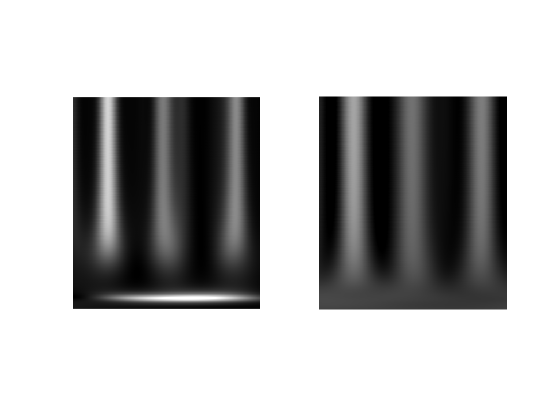

figure
subplot(1,2,1)
imshow(reshape(A(:,1)+avg_eeg_spectro,[581,513]))
subplot(1,2,2)
no_pcs = 15;
imshow(reshape(U(:,1:no_pcs)*Weights(1:no_pcs,1)+avg_eeg_spectro,[581,513]))

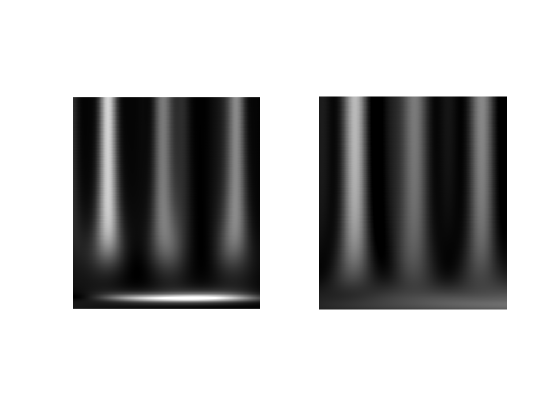

figure
subplot(1,2,1)
imshow(reshape(A(:,1)+avg_eeg_spectro,[581,513]))
subplot(1,2,2)
no_pcs = 16;
imshow(reshape(U(:,1:no_pcs)*Weights(1:no_pcs,1)+avg_eeg_spectro,[581,513]))

%Find the largest eigen vectos from k largest eigen values
[K, I] = sort(max(v_i),'descend');
%k=100;
k = 8;
%k = round(length(train_image_matrix(1,1,:)) * .10); %setting k for top 10% largest egien values
best_eigenvectors = zeros(length(u_i(:,1)),k);
for y = 1:k
   best_eigenvectors (:,y) =  u_i(:,I(y));
end

%% Representing EigenSpectros based on k best eigen vectors
wj = zeros(k,1);
%est_phi = zeros(length(A(:,1)),1);
omega = zeros(k,num_trn_images);
for w = 1:num_trn_images
    for i = 1:k
        %wj = eigen_spectros(:,i)' * A(:,1)
        omega (i,w) = U(:,i)' * A(:,w);
       % u = wj * eigen_spectros(:,i)
        
       % est_phi = u + est_phi
    end
end
%est_phi = wj * eigen_spectros(:,1);

%Build image based on best eigenvectors and weights
eigen_image = zeros(length(best_eigenvectors(:,1)),1)

eigen_image =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for z = 1:k
    image = omega(z,1)  * best_eigenvectors(:,1);
    eigen_image = image + eigen_image;
end

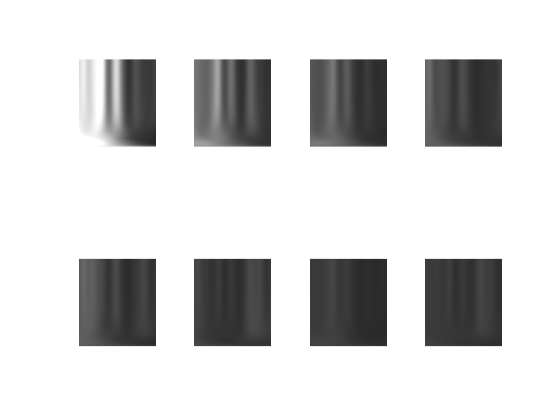

%% This will show each best eigenvector and orignal image they were based on
espec1 = reshape(best_eigenvectors(:,1),581,513);
espec2 = reshape(best_eigenvectors(:,2),581,513);
espec3 = reshape(best_eigenvectors(:,3),581,513);
espec4 = reshape(best_eigenvectors(:,4),581,513);
espec5 = reshape(best_eigenvectors(:,5),581,513);
espec6 = reshape(best_eigenvectors(:,6),581,513);
espec7 = reshape(best_eigenvectors(:,7),581,513);
espec8 = reshape(best_eigenvectors(:,8),581,513);
figure
subplot(2,4,1)
%ec1 = train_image_matrix(:,:,1) * est_phi(:,1);
imshow(espec1)
subplot(2,4,2)
%ec2 = train_image_matrix(:,:,1) * est_phi(2);
imshow(espec2)
subplot(2,4,3)
%ec3 = train_image_matrix(:,:,1) * est_phi(3);
imshow(espec3)
subplot(2,4,4)
%ec4 = train_image_matrix(:,:,1) * est_phi(4);
imshow(espec4)
subplot(2,4,5)
%ec5 = train_image_matrix(:,:,1) * est_phi(5);
imshow(espec5)
subplot(2,4,6)
%ec6 = train_image_matrix(:,:,1) * est_phi(6);
imshow(espec6)
subplot(2,4,7)
%ec7 = train_image_matrix(:,:,1) * est_phi(7);
imshow(espec7)
subplot(2,4,8)
imshow(espec8)

%imshow(train_image_matrix(:,:,1))

% figure
% subplot(1,5,1)
% imshow(train_image_matrix(:,:,1))
% title('Eigenspectros for T=0 example')
% subplot(1,5,2)


% J = imresize(train_image_matrix(:,:,200),[250 250])
% figure
% subplot(1,2,1);
% 
% imshow(J)
% title('Resized image to 256x256 pixels','Color','b')
% subplot(1,2,2);
% imshow(train_image_matrix(:,:,200)) 
% title('Original image size 581x513','Color','b')


